## TASK 4  PDFs of |x| under H0 and H1

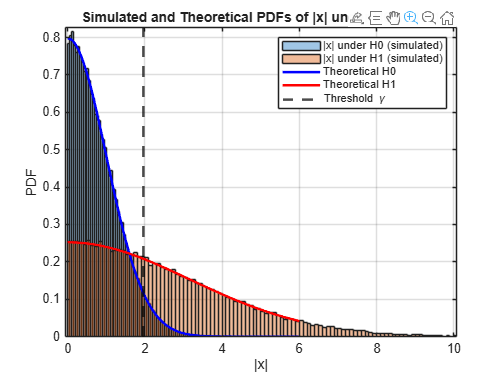

MC = 1e5;
sigma0 = 1;
sigma1 = sqrt(10);
gamma = 1.96;

% Simulated samples 
x0 = sigma0 * randn(MC,1);
x1 = sigma1 * randn(MC,1);

abs0 = abs(x0);
abs1 = abs(x1);

% Plot simulated histograms
figure;
histogram(abs0, 'Normalization','pdf','FaceAlpha',0.4); hold on;
histogram(abs1, 'Normalization','pdf','FaceAlpha',0.4);

% Theoretical half-normal PDFs
y = linspace(0,6,500);

f0 = (2/(sqrt(2*pi)*sigma0)) * exp(-(y.^2)/(2*sigma0^2));
f1 = (2/(sqrt(2*pi)*sigma1)) * exp(-(y.^2)/(2*sigma1^2));

plot(y, f0, 'b','LineWidth',2);
plot(y, f1, 'r','LineWidth',2);

% Threshold
xline(gamma,'k--','LineWidth',2);

legend('|x| under H0 (simulated)', '|x| under H1 (simulated)', ...
       'Theoretical H0', 'Theoretical H1', 'Threshold \gamma');

xlabel('|x|');
ylabel('PDF');
title('Simulated and Theoretical PDFs of |x| under H0 and H1');
grid on;